### Risoluzione letterale

clear
clc

syms t; % tempo
syms T; % Energia cinetica del sistema
syms U; % Energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta; % Altro angolo statico, vedi disegno
syms l_c l_a l_b m_a m_c m_r m_b g r;
syms J_r J_b J_a J_c;
syms q_1 q_1_p q_1_pp;
syms q_2 q_2_p q_2_pp;
syms C_m; % Coppia motrice

% Coordinate libere
syms phi(t); % Angolo letto dagli encoder
vel = diff(phi, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms q_1 q_1_p q_2 q_2_p;

## Calcolo componenti dinamiche e potenziali per ogni corpo rigido del sistema

Nello specifico abbiamo considerato il sistema composto da:

- Asta ($P_a$)

- Utente a bordo dello chassis ($P_c$)

- Chassis (o base) ($P_b$)

- Ruota ($P_r$) che poi sarà considerata con un contributo doppio, essendo 2 le ruote del sistema

Per ognuno di questi corpi rigidi siamo andati a calcolare:

- Coordinate spaziali nel sistema di riferimento XZ, con l'aggiunta delle coordinate angolari $$\rightarrow$$ vettore 3 x 1

- Vettore delle velocità $$\rightarrow$$ vettore 3 x 1

- Matrice delle masse $$\rightarrow$$ matrice 3 x 3

- Energia cinetica dello specifico corpo rigido $$\rightarrow$$ $T=\frac{1}{2\;}\bullet V^T \bullet M\bullet V$

- Energia potenziale dello specifico corpo rigido$$\rightarrow$$ $U$

- Lagrangiana dello specifico corpo rigido $$\rightarrow$$ $L=T-U$

### Asta $P_a$

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta];
V_a = diff(P_a, t);
M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a] % Matrice delle masse/inerzie

$$M\_a = \left(\begin{array}{ccc} m_{a} & 0 & 0\\ 0 & m_{a} & 0\\ 0 & 0 & J_{a} \end{array}\right)$$

T_a = collect(simplify(1/2 * transpose(V_a) * M_a * V_a, 'Steps', 50))

$$T\_a(t) = \frac{m_{a}\,{l_{a}}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{a}\,r^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+\frac{J_{a}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\,l_{a}\,r\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

U_a = m_a * g * l_a * cos(theta+beta);
L_a = T_a - U_a;

P_a_Test = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta)];
V_a_Test = diff(P_a_Test, t);
M_a_Test = [m_a,0; 0,m_a]; % Matrice delle masse/inerzie
inertia = 1/2 * (J_a + m_a * l_a^2) * (diff((theta + beta), t)^2)

$$inertia(t) = \left(\frac{m_{a}\,{l_{a}}^{2}}{2}+\frac{J_{a}}{2}\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

T_a_Test = collect(simplify((1/2 * transpose(V_a_Test) * M_a_Test * V_a_Test ), 'Steps', 50))

$$T\_a\_Test(t) = \frac{m_{a}\,{l_{a}}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{a}\,r^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+m_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\,l_{a}\,r\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

% collect(simplify(T_a_Test + 1/2 * (J_a + m_a * l_a^2) * (diff((theta + beta), t)^2), 'Steps', 50))
U_a_Test = m_a * g * l_a * cos(theta+beta);
L_a_Test = collect(simplify((T_a - U_a), 'Steps', 50));

### Utente  $P_c$

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]

$$P\_c(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)+l_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)\\ l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\\ \alpha +\theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t)

$$V\_c(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ -l_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c]

$$M\_c = \left(\begin{array}{ccc} m_{c} & 0 & 0\\ 0 & m_{c} & 0\\ 0 & 0 & J_{c} \end{array}\right)$$

T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c * cos(alpha+theta);
L_c = T_c - U_c

$$L\_c(t) = \begin{array}{l} \frac{J_{c}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{c}\,\left(r\,\frac{\partial }{\partial t}\varphi \left(t\right)+\sigma_{1}\right)\,\left(\frac{r\,\frac{\partial }{\partial t}\varphi \left(t\right)}{2}+\frac{\sigma_{1}}{2}\right)+\frac{{l_{c}}^{2}\,m_{c}\,{\sin\left(\alpha +\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,l_{c}\,m_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Chassis (o base)  $P_b$

P_b = [phi*r+l_b*sin(pi+theta); l_b*cos(pi+theta); pi+theta]

$$P\_b(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)-l_{b}\,\sin\left(\theta \left(t\right)\right)\\ -l_{b}\,\cos\left(\theta \left(t\right)\right)\\ \pi +\theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t)

$$V\_b(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ l_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b]

$$M\_b = \left(\begin{array}{ccc} m_{b} & 0 & 0\\ 0 & m_{b} & 0\\ 0 & 0 & J_{b} \end{array}\right)$$

T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b * cos(pi+theta);
L_b = T_b - U_b

$$L\_b(t) = \begin{array}{l} \frac{J_{b}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{b}\,\left(r\,\frac{\partial }{\partial t}\varphi \left(t\right)-\sigma_{1}\right)\,\left(\frac{r\,\frac{\partial }{\partial t}\varphi \left(t\right)}{2}-\frac{\sigma_{1}}{2}\right)+\frac{{l_{b}}^{2}\,m_{b}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+g\,l_{b}\,m_{b}\,\cos\left(\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=l_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Ruota $P_r$

P_r = [phi*r; 0; phi]

$$P\_r(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)\\ 0\\ \varphi \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} m_{r} & 0 & 0\\ 0 & m_{r} & 0\\ 0 & 0 & J_{r} \end{array}\right)$$

T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r

$$L\_r(t) = \frac{m_{r}\,r^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+\frac{J_{r}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

### Lagrangiana dell'intero sistema

L = collect(simplify(2*L_r + L_a + L_b + L_c))

$$L(t) = \begin{array}{l} J_{r}\,\sigma_{2}+\frac{J_{a}\,\sigma_{1}}{2}+\frac{J_{b}\,\sigma_{1}}{2}+\frac{J_{c}\,\sigma_{1}}{2}+\frac{{l_{a}}^{2}\,m_{a}\,\sigma_{1}}{2}+\frac{{l_{b}}^{2}\,m_{b}\,\sigma_{1}}{2}+\frac{{l_{c}}^{2}\,m_{c}\,\sigma_{1}}{2}+\frac{m_{a}\,r^{2}\,\sigma_{2}}{2}+\frac{m_{b}\,r^{2}\,\sigma_{2}}{2}+\frac{m_{c}\,r^{2}\,\sigma_{2}}{2}+m_{r}\,r^{2}\,\sigma_{2}-g\,l_{c}\,m_{c}\,\sigma_{4}-g\,l_{a}\,m_{a}\,\sigma_{3}+g\,l_{b}\,m_{b}\,\cos\left(\theta \left(t\right)\right)+l_{c}\,m_{c}\,r\,\sigma_{4}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{a}\,m_{a}\,r\,\sigma_{3}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}\\ \sigma_{3}=\cos\left(\beta +\theta \left(t\right)\right)\\ \sigma_{4}=\cos\left(\alpha +\theta \left(t\right)\right) \end{array}$$

L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}); % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

## Equazioni del moto

Andiamo ora a calcolare le equazioni del moto, considerando, come coordinate libere

- 
$$\phi =q_{1\;} =\textrm{angolo}\;\textrm{di}\;\textrm{rotazione}\;\textrm{delle}\;\textrm{ruote}$$


- 
$$\theta =q_2 =\textrm{inclinazione}\;\textrm{chassis}$$


Utilizziamo questa formulazione:


$$\frac{d}{\textrm{dt}}\left(\frac{\partial }{\partial \overset{\ldotp }{q} }L\right)-\frac{\partial }{\partial q}L=\textrm{extern}\;\textrm{force}$$


### Calcolo equazioni del moto rispetto a $$q_1$$ phi

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);

E_L_phi = collect(simplify(dL_dvel_dt - dL_dphi == C_m))

$$E\_L\_phi(t) = \begin{array}{l} C_{m}+l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}+l_{c}\,m_{c}\,r\,\sin\left(\alpha +\theta \left(t\right)\right)\,\sigma_{2}+l_{a}\,m_{a}\,r\,\sin\left(\beta +\theta \left(t\right)\right)\,\sigma_{2}=2\,J_{r}\,\sigma_{1}+m_{a}\,r^{2}\,\sigma_{1}+m_{b}\,r^{2}\,\sigma_{1}+m_{c}\,r^{2}\,\sigma_{1}+2\,m_{r}\,r^{2}\,\sigma_{1}+l_{b}\,m_{b}\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+l_{c}\,m_{c}\,r\,\cos\left(\alpha +\theta \left(t\right)\right)\,\sigma_{3}+l_{a}\,m_{a}\,r\,\cos\left(\beta +\theta \left(t\right)\right)\,\sigma_{3}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

### Calcolo equazioni del moto rispetto a $q_2$ theta

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(simplify(dL_dvel_ang_dt - dL_dtheta == - C_m))

$$E\_L\_theta(t) = \begin{array}{l} C_{m}+J_{a}\,\sigma_{1}+J_{b}\,\sigma_{1}+J_{c}\,\sigma_{1}+{l_{a}}^{2}\,m_{a}\,\sigma_{1}+{l_{b}}^{2}\,m_{b}\,\sigma_{1}+{l_{c}}^{2}\,m_{c}\,\sigma_{1}+g\,l_{b}\,m_{b}\,\sin\left(\theta \left(t\right)\right)+l_{c}\,m_{c}\,r\,\cos\left(\alpha +\theta \left(t\right)\right)\,\sigma_{2}+l_{a}\,m_{a}\,r\,\cos\left(\beta +\theta \left(t\right)\right)\,\sigma_{2}=l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}+g\,l_{c}\,m_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)+g\,l_{a}\,m_{a}\,\sin\left(\beta +\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

## Risoluzione delle equazioni del moto

acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q_1_pp,q_2_pp}), subs(E_L_phi, {acc,acc_ang},{q_1_pp,q_2_pp})];
S = solve(eqns, q_1_pp ,q_2_pp)

S = struct with fields:
    q_1_pp: [1×1 sym]
    q_2_pp: [1×1 sym]


phi2 = S.q_1_pp

theta2 = S.q_2_pp

Avrò 2 equilibri per l'angolo theta

- 0 --> equilibrio instabile

- k + $\pi \;$ --> equilibrio stabile

Per l'altra variabile di stato (posizione x --> angolo phi) l'equilibrio non è rilevante ai fini del controllo dell'equilibrio del segway.

Andiamo quindi a linearizzare intorno all'equilibrio instabile = [phi, vel, theta, vel_ang] = [0,0,0,0].

Il vettore di stato con il quale andremo a lavorare è il seguente

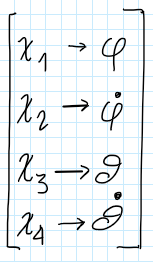

Inoltre, per definire il nostro sistema SIMO in forma matriciale, avremo bisogno del supporto delle matrici A-B-C-D. Per fare questo definiamo queste funzioni di supporto:

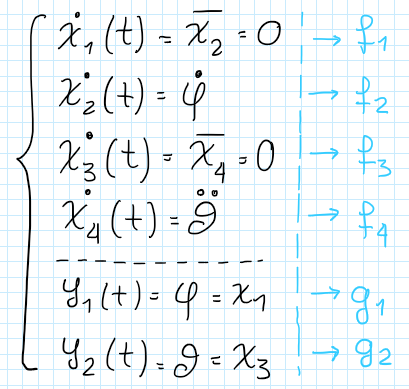

Da qui è quindi possibile poi ricavare le matrici A-B-C-D come segue:

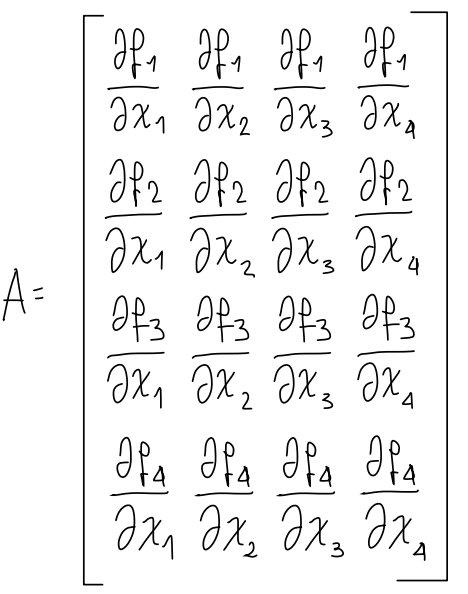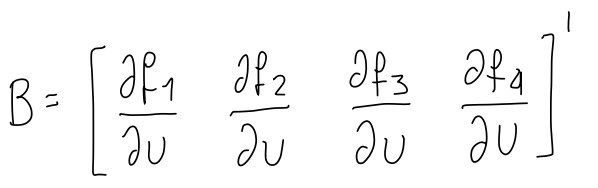

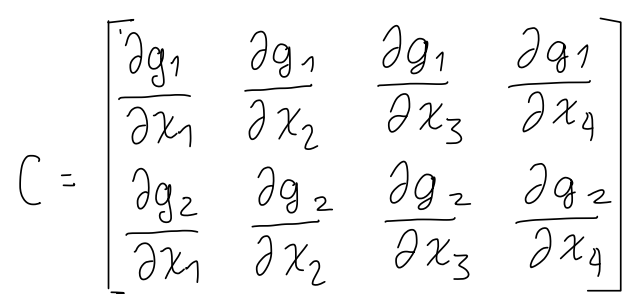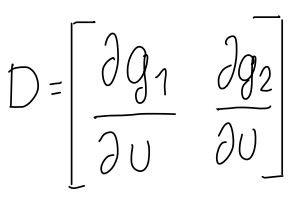

Dove le matrici A e B hanno nello specifico questa forma:

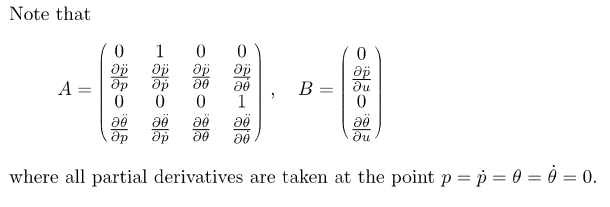

syms u;
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u});

%phi, phi_primo, theta, theta_primo, C_m (u = INPUT)
equilibrio = {0,0,0,0,0};

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]


B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41]

$$B = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{m_{a}\,{l_{a}}^{2}+m_{a}\,r\,\cos\left(\beta \right)\,l_{a}+m_{b}\,{l_{b}}^{2}-m_{b}\,r\,l_{b}+m_{c}\,{l_{c}}^{2}+m_{c}\,r\,\cos\left(\alpha \right)\,l_{c}+J_{a}+J_{b}+J_{c}}{\sigma_{1}}\\ 0\\ -\frac{2\,J_{r}+m_{a}\,r^{2}+m_{b}\,r^{2}+m_{c}\,r^{2}+2\,m_{r}\,r^{2}-l_{b}\,m_{b}\,r+l_{c}\,m_{c}\,r\,\cos\left(\alpha \right)+l_{a}\,m_{a}\,r\,\cos\left(\beta \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,J_{a}\,J_{r}+2\,J_{b}\,J_{r}+2\,J_{c}\,J_{r}+{l_{a}}^{2}\,{m_{a}}^{2}\,r^{2}+{l_{c}}^{2}\,{m_{c}}^{2}\,r^{2}+2\,J_{r}\,{l_{a}}^{2}\,m_{a}+2\,J_{r}\,{l_{b}}^{2}\,m_{b}+2\,J_{r}\,{l_{c}}^{2}\,m_{c}+J_{a}\,m_{a}\,r^{2}+J_{a}\,m_{b}\,r^{2}+J_{b}\,m_{a}\,r^{2}+J_{a}\,m_{c}\,r^{2}+J_{b}\,m_{b}\,r^{2}+J_{c}\,m_{a}\,r^{2}+J_{b}\,m_{c}\,r^{2}+J_{c}\,m_{b}\,r^{2}+J_{c}\,m_{c}\,r^{2}+2\,J_{a}\,m_{r}\,r^{2}+2\,J_{b}\,m_{r}\,r^{2}+2\,J_{c}\,m_{r}\,r^{2}+{l_{a}}^{2}\,m_{a}\,m_{b}\,r^{2}+{l_{a}}^{2}\,m_{a}\,m_{c}\,r^{2}+{l_{b}}^{2}\,m_{a}\,m_{b}\,r^{2}+{l_{b}}^{2}\,m_{b}\,m_{c}\,r^{2}+{l_{c}}^{2}\,m_{a}\,m_{c}\,r^{2}+{l_{c}}^{2}\,m_{b}\,m_{c}\,r^{2}+2\,{l_{a}}^{2}\,m_{a}\,m_{r}\,r^{2}+2\,{l_{b}}^{2}\,m_{b}\,m_{r}\,r^{2}+2\,{l_{c}}^{2}\,m_{c}\,m_{r}\,r^{2}-{l_{c}}^{2}\,{m_{c}}^{2}\,r^{2}\,{\cos\left(\alpha \right)}^{2}-{l_{a}}^{2}\,{m_{a}}^{2}\,r^{2}\,{\cos\left(\beta \right)}^{2}+2\,l_{b}\,l_{c}\,m_{b}\,m_{c}\,r^{2}\,\cos\left(\alpha \right)+2\,l_{a}\,l_{b}\,m_{a}\,m_{b}\,r^{2}\,\cos\left(\beta \right)-2\,l_{a}\,l_{c}\,m_{a}\,m_{c}\,r^{2}\,\cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}$$


C = [0,0,1,0] % Riportiamo in uscita solamente l'angolo

C =      0     0     1     0


%C = eye(4); % Riportiamo in uscita tutte le variabili di stato
D = 0

D = 0


syms s G(s);
G = collect(simplify(C*(s*eye(4)-A)^(-1)*B+D))